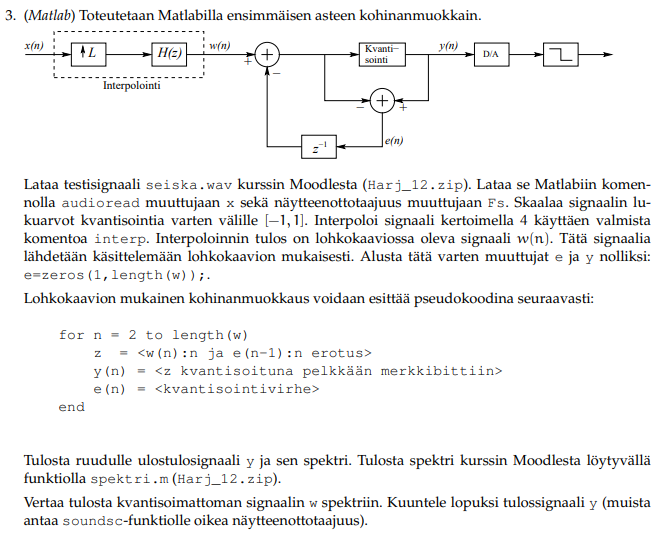

[y,Fs]=audioread("seiska.wav");

% uusi_y=quant(y,1);
% sum(uusi_y==1)+sum(uusi_y==0)+sum(uusi_y==-1)
% w=interp(uusi_y,4);
rescale(y,-1,1);
w=interp(y,4);

e=zeros(1,length(w));
y=zeros(1,length(w));

for n = 2 : length(w)
    z = w(n)-e(1,n-1);
    y(n) = quant(z,1);
    e(1,n) = y(n)-z;
end

spektri (y)

ans =    28.7344   12.0065    0.1045    0.1759    0.3490    0.1257    0.1842    0.2335    0.1375    0.1669    0.1389    0.3307    0.1922    0.2914    0.2685    0.2366    0.4037    0.6306    0.0669    0.2604    0.1214    0.1933    0.2788    0.5035    0.6759    0.6321    0.7496    0.6939    0.7265    0.9473    0.8514    0.7568    0.8154    0.8765    0.4271    0.9076    0.7869    0.7664    0.6457    0.8693    1.1038    0.4285    0.7332    0.7579    0.4267    0.3229    0.1712    0.3908    0.6752    0.8906


%soundsc (y,Fs*4)
figure
spektri (w)

ans =    28.7441   11.9761    0.1148    0.0844    0.2325    0.1365    0.1028    0.1903    0.2697    0.0964    0.0713    0.0974    0.0920    0.0860    0.2146    0.1342    0.1284    0.2205    0.1073    0.1447    0.2625    0.0872    0.2713    0.1189    0.0490    0.1518    0.0581    0.0570    0.2274    0.0463    0.0410    0.1609    0.0453    0.1386    0.0898    0.2486    0.1612    0.2704    0.0452    0.2110    0.1875    0.2070    0.2298    0.3524    0.3033    0.3122    0.1062    0.0990    0.1571    0.6125


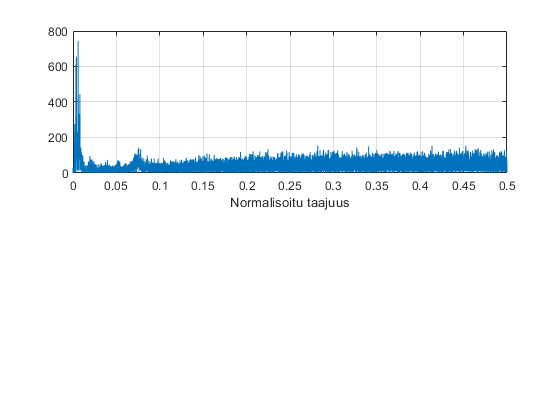

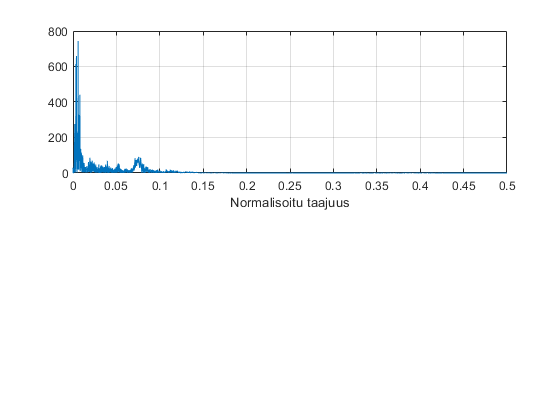

pause(2)

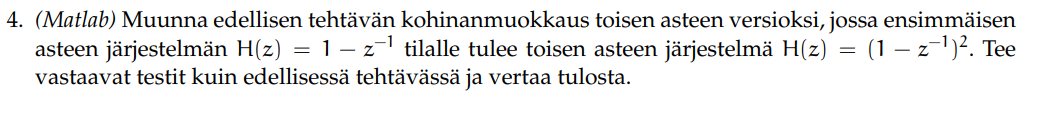

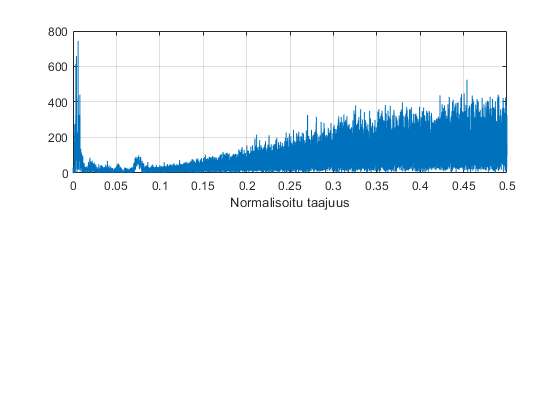

ans =    28.7282   11.9920    0.1291    0.0912    0.2171    0.1385    0.0925    0.1999    0.2546    0.0968    0.0636    0.0955    0.0816    0.0713    0.1995    0.1487    0.1195    0.2101    0.0916    0.1607    0.2472    0.0982    0.2693    0.1063    0.0525    0.1408    0.0498    0.0568    0.2150    0.0628    0.0306    0.1453    0.0592    0.1232    0.1029    0.2338    0.1763    0.2562    0.0574    0.2003    0.1878    0.1949    0.2216    0.3596    0.2935    0.2997    0.1097    0.1117    0.1435    0.6158


e=zeros(1,length(w));
y=zeros(1,length(w));

for n = 3 : length(w)
    z = w(n)-2*e(1,n-1)+e(1,n-2);
    y(n) = quant(z,1);
    e(1,n) = y(n)-z;
end
figure
spektri (y)

%soundsc (y,Fs*4)
figure
spektri (w)

ans =    28.7441   11.9761    0.1148    0.0844    0.2325    0.1365    0.1028    0.1903    0.2697    0.0964    0.0713    0.0974    0.0920    0.0860    0.2146    0.1342    0.1284    0.2205    0.1073    0.1447    0.2625    0.0872    0.2713    0.1189    0.0490    0.1518    0.0581    0.0570    0.2274    0.0463    0.0410    0.1609    0.0453    0.1386    0.0898    0.2486    0.1612    0.2704    0.0452    0.2110    0.1875    0.2070    0.2298    0.3524    0.3033    0.3122    0.1062    0.0990    0.1571    0.6125


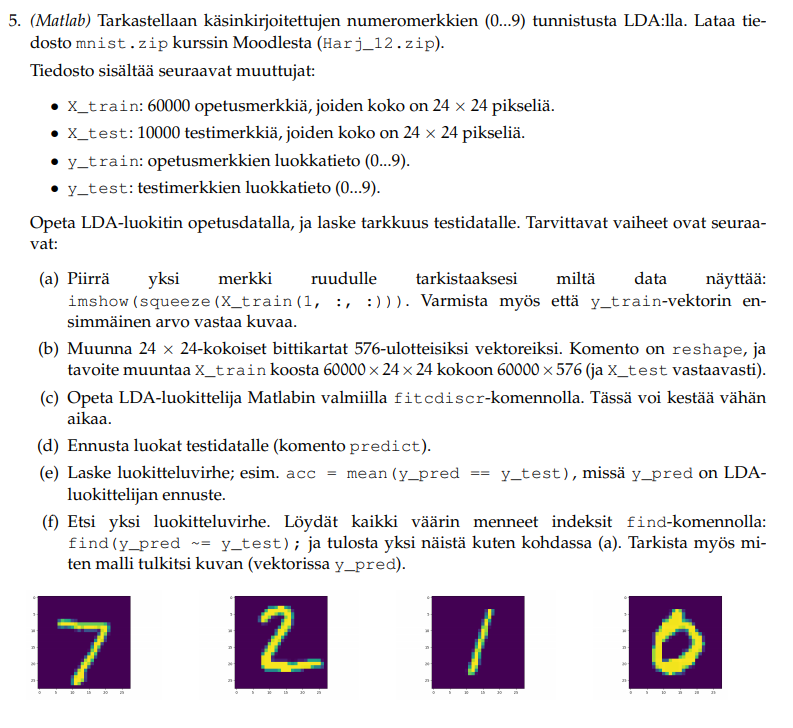

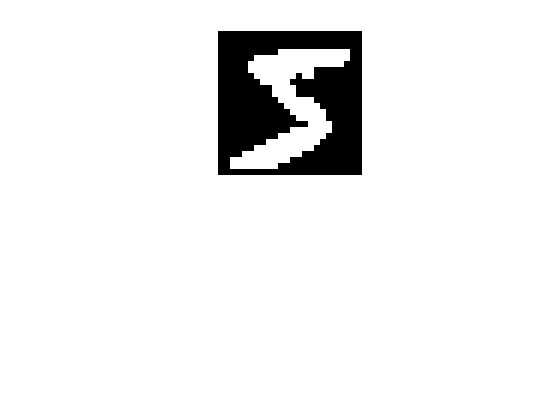

clear all
load mnist.mat
%a
imshow(squeeze(X_train(1, :, :)))

y_train(1)

ans = 5

%b
reXTrain = reshape(X_train,[],576);
reXTest = reshape(X_test,[],576);
%c
Mdl = fitcdiscr(reXTrain,y_train)

Mdl =   ClassificationDiscriminant
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 60000
              DiscrimType: 'linear'
                       Mu: [10×576 double]
                   Coeffs: [10×10 struct]


  Properties, Methods


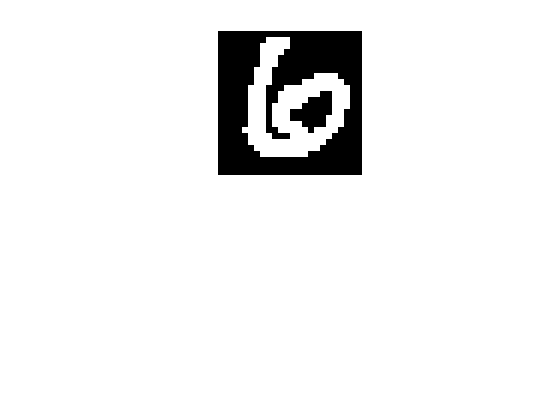


%d
y_pred=predict(Mdl,reXTest);
%e
acc = mean(y_pred == y_test);
%f
index=find(y_pred ~= y_test);
imshow(squeeze(X_test(index(1), :, :)))

y_pred(index(1))

ans = 8